clc
clear all

% Get RIR from the sine sweep measurements
% Deconvolution

%TODO%
[sine_sweep,fs] = audioread('python_sweep_files/inverse.wav');
sine_sweep = sine_sweep(97:end); % Had to remove the first element because it was 0 and the deconv function complained
length(sine_sweep)

ans = 479904

number_of_discrete_positions = 12;
number_of_speakers = 2;

number_of_mics = ['A','B','C','D','E','F'];

speakers_all_discrete_positions = cell(number_of_discrete_positions,number_of_speakers);

for i=1:number_of_discrete_positions
    for j=1:length(number_of_mics)
        %disp(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(3+i) '.wav'])
        %disp('-----')
        if i+3 >= 10
            [audioData, fs] = audioread(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(3+i) '.wav']);
        else
            [audioData, fs] = audioread(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_00' num2str(3+i) '.wav']);
        end
        truncatedAudioData = audioData(1:length(sine_sweep)); %truncatedAudioData = audioData(1:630000);

        % TODO:
        rir = deconv(truncatedAudioData, sine_sweep);

        speakers_all_discrete_positions{i,1}(:,j) = rir;
    end
end

for i=1:number_of_discrete_positions
    for j=1:length(number_of_mics)
        %disp(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(15+i) '.wav'])
        %disp('-----')
        audioData = audioread(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(15+i) '.wav']);
        truncatedAudioData = audioData(1:length(sine_sweep)); %truncatedAudioData = audioData(1:630000);

        % TODO:
        rir = deconv(truncatedAudioData, sine_sweep);

        speakers_all_discrete_positions{i,2}(:,j) = rir;
    end
end        

a = createSDMStruct('DefaultArray','GRASVI50','fs',fs,'winLen',15);

User-defined SDM Settings are used :
           fs: 48000
            c: 345
       winLen: 15
    parFrames: 8192
    showArray: 0
      micLocs: [6×3 double]



DOA = cell(number_of_discrete_positions,number_of_speakers);
P = cell(number_of_discrete_positions,number_of_speakers);

for i=1:number_of_discrete_positions
    DOA{i,1} = SDMbf(speakers_all_discrete_positions{i,1}, a);
end

Started SDM processing
Ended SDM processing in 0.0098389 seconds.
Started SDM processing
Ended SDM processing in 0.0020591 seconds.
Started SDM processing
Ended SDM processing in 0.0014618 seconds.
Started SDM processing
Ended SDM processing in 0.0008032 seconds.
Started SDM processing
Ended SDM processing in 0.0061657 seconds.
Started SDM processing
Ended SDM processing in 0.0001238 seconds.
Started SDM processing
Ended SDM processing in 3.11e-05 seconds.
Started SDM processing
Ended SDM processing in 2.37e-05 seconds.
Started SDM processing
Ended SDM processing in 2.61e-05 seconds.
Started SDM processing
Ended SDM processing in 2.38e-05 seconds.
Started SDM processing
Ended SDM processing in 2.3e-05 seconds.
Started SDM processing
Ended SDM processing in 2.21e-05 seconds.


for i=1:number_of_discrete_positions
    DOA{i,2} = SDMbf(speakers_all_discrete_positions{i,2}, a);
end

Started SDM processing
Ended SDM processing in 6.16e-05 seconds.
Started SDM processing
Ended SDM processing in 3.33e-05 seconds.
Started SDM processing
Ended SDM processing in 2.72e-05 seconds.
Started SDM processing
Ended SDM processing in 2.3e-05 seconds.
Started SDM processing
Ended SDM processing in 2.74e-05 seconds.
Started SDM processing
Ended SDM processing in 2.53e-05 seconds.
Started SDM processing
Ended SDM processing in 2.06e-05 seconds.
Started SDM processing
Ended SDM processing in 2.18e-05 seconds.
Started SDM processing
Ended SDM processing in 3.96e-05 seconds.
Started SDM processing
Ended SDM processing in 2.67e-05 seconds.
Started SDM processing
Ended SDM processing in 1.93e-05 seconds.
Started SDM processing
Ended SDM processing in 1.94e-05 seconds.


% TAKE THE MIDDLE ONE OF THE MICROPHONE ARRAY, THIS IS THE TOP ONE E

for i=1:number_of_discrete_positions
    P{i,1} = speakers_all_discrete_positions{i,1}(:,5);
end

for i=1:number_of_discrete_positions
    P{i,2} = speakers_all_discrete_positions{i,2}(:,5);
end

%save variables in file to use it in another file
save("pressure.mat","P")
save("DOA.mat","DOA")

%save('.\outputDataCalculateSRIR\cell1', 'P')

% Export P, DOA and RIRI to csv file, speaker 1
%for i=1:number_of_discrete_positions
%    csvwrite(['.\outputDataCalculateSRIR\RIR_output_position' num2str(i) '.csv'], speakers_all_discrete_positions{i,1});
%    csvwrite(['.\outputDataCalculateSRIR\DOA_output_position' num2str(i) '.csv'], DOA{i,1});
%    csvwrite(['.\outputDataCalculateSRIR\P_output_position' num2str(i) '.csv'], P{i,1});
%end

% Export P, DOA and RIRI to csv file, speaker 2
% for i=1:number_of_discrete_positions
%     csvwrite(['.\outputDataCalculateSRIR\RIR_output_position' num2str(i) '.csv'], speakers_all_discrete_positions{i,2});
%     csvwrite(['.\outputDataCalculateSRIR\DOA_output_position' num2str(i) '.csv'], DOA{i,2});
%     csvwrite(['.\outputDataCalculateSRIR\P_output_position' num2str(i) '.csv'], P{i,2});
% end

v = createVisualizationStruct('DefaultRoom','LargeRoom',...
    'name','Pori, Concert Hall','fs',fs,'t',[2 5 10 20 50 100 200 2000]);

createVisualizationStruct : User-defined visualization settings are used :
              fs: 48000
           plane: 'lateral'
             DOI: 'forward'
       plotStyle: 'line'
            name: 'Pori, Concert Hall'
             res: 1
               t: [2 5 10 20 50 100 200 2000]
          colors: [8×3 double]
       dBSpacing: 6
      DOASpacing: 30
      dBDynamics: 45
       linewidth: [1 1 1 1 1 1 1 1]
        showGrid: 1
    smoothMethod: 'average'
       smoothRes: 3



Started visualization of parameters.


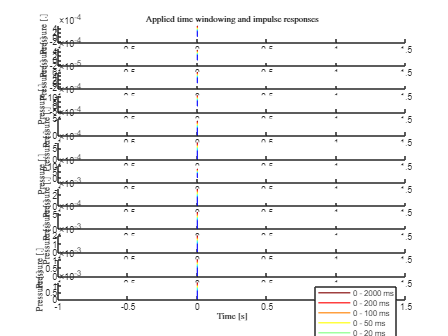

Ended visualization of parameters in 0.63863 seconds.


% For visualization purposes, set the text interpreter to latex
set(0,'DefaultTextInterpreter','latex')
parameterVisualization(P, v);

Started time-frequency visualization.


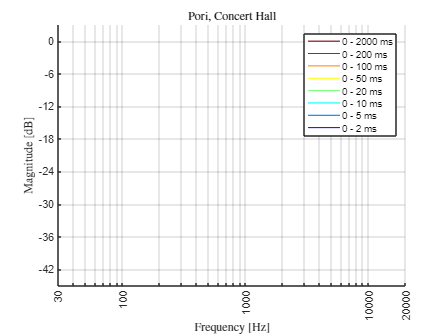

Ended time-frequency visualization in 0.16159 seconds.


timeFrequencyVisualization(P, v)

Started spatio-temporal visualization.


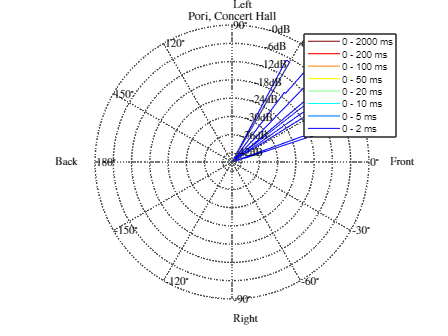

Ended spatio-temporal visualization in 0.39555 seconds.


v.plane = 'lateral';
spatioTemporalVisualization(P, DOA, v)

Started spatio-temporal visualization.


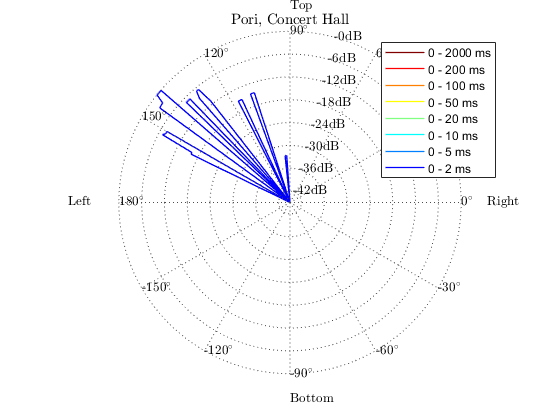

Ended spatio-temporal visualization in 0.24495 seconds.


v.plane = 'transverse';
spatioTemporalVisualization(P, DOA, v)

Started spatio-temporal visualization.


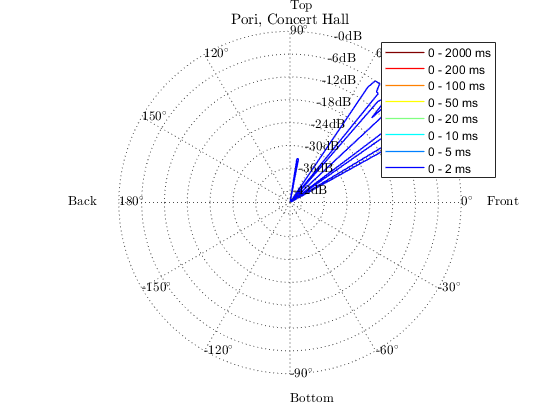

Ended spatio-temporal visualization in 0.27084 seconds.


v.plane = 'median';
spatioTemporalVisualization(P, DOA, v)

% Plot RIR in room
% https://nl.mathworks.com/help/audio/ug/room-impulse-response-simulation-with-image-source-method-and-hrtf-interpolation.html